%计算考虑化学作用后的三锁体系
clear all
syms e r o l k;

y1=[];
y2=[];
Plock=[];
Vlock=[];
Vopen=[];
s1=[];
s2=[];

m=2;

for l=3:0.1:7
    N=10000; %随机点个数
    X=l*rand(N,m); %[x1,x2,...,xm] 其中xi为N维列向量,xi=X(:,i)
    for i=1:1:N
        X(i,:)=sort(X(i,:));
    end
    x1=X(:,1);
    x2=X(:,2);    
    for k = 0:0.1:2
%计算锁死所占成分
        fun1 = @(x1,x2) P(x1).^(2*k).*P(x2-x1).^(2*k).*P(l-x2).^(k);
        for i=1:1:N
            s1=[s1,fun1(x1(i),x2(i))];
        end
    
        V_lock = (m+1)*1/N*1/2*l.^2.*sum(s1);
        s1=[];
%计算开放所占成分
        fun2 = @(x1,x2) P(l-x2).^(k).*P(x2).^k.*P(x2-x1).^k.*P(l-x1).^k.*P(x1).^k;
        for i=1:1:N
            s2=[s2,fun2(x1(i),x2(i))];
        end
        V_open = (2.*m-2)*1/N*1/2*l.^2.*sum(s2);
        s2=[];
        P_lock = V_lock/(V_lock + V_open) %计算锁死所占比例
        Plock=[Plock,P_lock];
    end
end

P_lock = 0.6000

P_lock = 0.5208

P_lock = 0.5262

P_lock = 0.5380

P_lock = 0.5536

P_lock = 0.5704

P_lock = 0.5866

P_lock = 0.6014

P_lock = 0.6145

P_lock = 0.6258

P_lock = 0.6355

P_lock = 0.6439

P_lock = 0.6511

P_lock = 0.6573

P_lock = 0.6629

P_lock = 0.6678

P_lock = 0.6723

P_lock = 0.6765

P_lock = 0.6805

P_lock = 0.6843

P_lock = 0.6881

P_lock = 0.6000

P_lock = 0.5686

P_lock = 0.6104

P_lock = 0.6552

P_lock = 0.7003

P_lock = 0.7436

P_lock = 0.7837

P_lock = 0.8199

P_lock = 0.8517

P_lock = 0.8792

P_lock = 0.9024

P_lock = 0.9218

P_lock = 0.9377

P_lock = 0.9507

P_lock = 0.9611

P_lock = 0.9695

P_lock = 0.9761

P_lock = 0.9813

P_lock = 0.9854

P_lock = 0.9886

P_lock = 0.9912

P_lock = 0.6000

P_lock = 0.5977

P_lock = 0.6690

P_lock = 0.7385

P_lock = 0.7988

P_lock = 0.8482

P_lock = 0.8871

P_lock = 0.9169

P_lock = 0.9394

P_lock = 0.9560

P_lock = 0.9682

P_lock = 0.9771

P_lock = 0.9835

P_lock = 0.9882

P_lock = 0.9915

P_lock = 0.9939

P_lock = 0.9957

P_lock = 0.9969

P_lock = 0.9978

P_lock = 0.9984

P_lock = 0.9989

P_lock = 0.6000

P_lock = 0.6181

P_lock = 0.6943

P_lock = 0.7645

P_lock = 0.8243

P_lock = 0.8723

P_lock = 0.9091

P_lock = 0.9362

P_lock = 0.9557

P_lock = 0.9695

P_lock = 0.9791

P_lock = 0.9857

P_lock = 0.9903

P_lock = 0.9934

P_lock = 0.9955

P_lock = 0.9970

P_lock = 0.9979

P_lock = 0.9986

P_lock = 0.9990

P_lock = 0.9994

P_lock = 0.9996

P_lock = 0.6000

P_lock = 0.6218

P_lock = 0.7026

P_lock = 0.7741

P_lock = 0.8331

P_lock = 0.8796

P_lock = 0.9146

P_lock = 0.9402

P_lock = 0.9585

P_lock = 0.9714

P_lock = 0.9803

P_lock = 0.9865

P_lock = 0.9908

P_lock = 0.9937

P_lock = 0.9957

P_lock = 0.9971

P_lock = 0.9980

P_lock = 0.9986

P_lock = 0.9991

P_lock = 0.9994

P_lock = 0.9996

P_lock = 0.6000

P_lock = 0.6327

P_lock = 0.7089

P_lock = 0.7769

P_lock = 0.8333

P_lock = 0.8780

P_lock = 0.9122

P_lock = 0.9377

P_lock = 0.9562

P_lock = 0.9694

P_lock = 0.9788

P_lock = 0.9853

P_lock = 0.9899

P_lock = 0.9930

P_lock = 0.9952

P_lock = 0.9967

P_lock = 0.9977

P_lock = 0.9985

P_lock = 0.9989

P_lock = 0.9993

P_lock = 0.9995

P_lock = 0.6000

P_lock = 0.6313

P_lock = 0.7018

P_lock = 0.7666

P_lock = 0.8218

P_lock = 0.8667

P_lock = 0.9019

P_lock = 0.9287

P_lock = 0.9487

P_lock = 0.9634

P_lock = 0.9741

P_lock = 0.9817

P_lock = 0.9871

P_lock = 0.9910

P_lock = 0.9937

P_lock = 0.9956

P_lock = 0.9969

P_lock = 0.9978

P_lock = 0.9985

P_lock = 0.9990

P_lock = 0.9993

P_lock = 0.6000

P_lock = 0.6336

P_lock = 0.7019

P_lock = 0.7640

P_lock = 0.8174

P_lock = 0.8614

P_lock = 0.8964

P_lock = 0.9236

P_lock = 0.9442

P_lock = 0.9595

P_lock = 0.9708

P_lock = 0.9791

P_lock = 0.9851

P_lock = 0.9894

P_lock = 0.9924

P_lock = 0.9946

P_lock = 0.9962

P_lock = 0.9973

P_lock = 0.9981

P_lock = 0.9987

P_lock = 0.9991

P_lock = 0.6000

P_lock = 0.6347

P_lock = 0.6997

P_lock = 0.7582

P_lock = 0.8089

P_lock = 0.8514

P_lock = 0.8860

P_lock = 0.9136

P_lock = 0.9352

P_lock = 0.9518

P_lock = 0.9644

P_lock = 0.9739

P_lock = 0.9810

P_lock = 0.9862

P_lock = 0.9900

P_lock = 0.9928

P_lock = 0.9948

P_lock = 0.9963

P_lock = 0.9973

P_lock = 0.9981

P_lock = 0.9986

P_lock = 0.6000

P_lock = 0.6344

P_lock = 0.6938

P_lock = 0.7486

P_lock = 0.7973

P_lock = 0.8393

P_lock = 0.8744

P_lock = 0.9032

P_lock = 0.9262

P_lock = 0.9444

P_lock = 0.9584

P_lock = 0.9692

P_lock = 0.9773

P_lock = 0.9834

P_lock = 0.9880

P_lock = 0.9913

P_lock = 0.9938

P_lock = 0.9956

P_lock = 0.9968

P_lock = 0.9978

P_lock = 0.9984

P_lock = 0.6000

P_lock = 0.6312

P_lock = 0.6893

P_lock = 0.7431

P_lock = 0.7911

P_lock = 0.8328

P_lock = 0.8680

P_lock = 0.8972

P_lock = 0.9209

P_lock = 0.9397

P_lock = 0.9546

P_lock = 0.9661

P_lock = 0.9749

P_lock = 0.9815

P_lock = 0.9865

P_lock = 0.9902

P_lock = 0.9929

P_lock = 0.9949

P_lock = 0.9964

P_lock = 0.9974

P_lock = 0.9982

P_lock = 0.6000

P_lock = 0.6296

P_lock = 0.6843

P_lock = 0.7353

P_lock = 0.7818

P_lock = 0.8231

P_lock = 0.8588

P_lock = 0.8891

P_lock = 0.9141

P_lock = 0.9345

P_lock = 0.9506

P_lock = 0.9633

P_lock = 0.9730

P_lock = 0.9804

P_lock = 0.9858

P_lock = 0.9899

P_lock = 0.9929

P_lock = 0.9950

P_lock = 0.9965

P_lock = 0.9976

P_lock = 0.9983

P_lock = 0.6000

P_lock = 0.6299

P_lock = 0.6823

P_lock = 0.7319

P_lock = 0.7774

P_lock = 0.8182

P_lock = 0.8539

P_lock = 0.8844

P_lock = 0.9099

P_lock = 0.9308

P_lock = 0.9476

P_lock = 0.9608

P_lock = 0.9711

P_lock = 0.9789

P_lock = 0.9848

P_lock = 0.9891

P_lock = 0.9923

P_lock = 0.9946

P_lock = 0.9962

P_lock = 0.9974

P_lock = 0.9982

P_lock = 0.6000

P_lock = 0.6297

P_lock = 0.6784

P_lock = 0.7256

P_lock = 0.7698

P_lock = 0.8101

P_lock = 0.8460

P_lock = 0.8772

P_lock = 0.9038

P_lock = 0.9258

P_lock = 0.9437

P_lock = 0.9579

P_lock = 0.9690

P_lock = 0.9775

P_lock = 0.9839

P_lock = 0.9885

P_lock = 0.9920

P_lock = 0.9944

P_lock = 0.9961

P_lock = 0.9974

P_lock = 0.9982

P_lock = 0.6000

P_lock = 0.6292

P_lock = 0.6780

P_lock = 0.7251

P_lock = 0.7695

P_lock = 0.8104

P_lock = 0.8470

P_lock = 0.8790

P_lock = 0.9062

P_lock = 0.9287

P_lock = 0.9468

P_lock = 0.9610

P_lock = 0.9719

P_lock = 0.9800

P_lock = 0.9859

P_lock = 0.9902

P_lock = 0.9933

P_lock = 0.9954

P_lock = 0.9969

P_lock = 0.9979

P_lock = 0.9986

P_lock = 0.6000

P_lock = 0.6269

P_lock = 0.6741

P_lock = 0.7201

P_lock = 0.7637

P_lock = 0.8041

P_lock = 0.8406

P_lock = 0.8728

P_lock = 0.9005

P_lock = 0.9235

P_lock = 0.9423

P_lock = 0.9572

P_lock = 0.9688

P_lock = 0.9775

P_lock = 0.9840

P_lock = 0.9888

P_lock = 0.9922

P_lock = 0.9946

P_lock = 0.9963

P_lock = 0.9975

P_lock = 0.9983

P_lock = 0.6000

P_lock = 0.6269

P_lock = 0.6722

P_lock = 0.7167

P_lock = 0.7597

P_lock = 0.8002

P_lock = 0.8374

P_lock = 0.8705

P_lock = 0.8992

P_lock = 0.9232

P_lock = 0.9426

P_lock = 0.9580

P_lock = 0.9698

P_lock = 0.9786

P_lock = 0.9850

P_lock = 0.9896

P_lock = 0.9929

P_lock = 0.9952

P_lock = 0.9967

P_lock = 0.9978

P_lock = 0.9985

P_lock = 0.6000

P_lock = 0.6252

P_lock = 0.6689

P_lock = 0.7116

P_lock = 0.7530

P_lock = 0.7922

P_lock = 0.8286

P_lock = 0.8616

P_lock = 0.8905

P_lock = 0.9152

P_lock = 0.9356

P_lock = 0.9521

P_lock = 0.9649

P_lock = 0.9747

P_lock = 0.9821

P_lock = 0.9874

P_lock = 0.9913

P_lock = 0.9940

P_lock = 0.9959

P_lock = 0.9972

P_lock = 0.9981

P_lock = 0.6000

P_lock = 0.6253

P_lock = 0.6671

P_lock = 0.7090

P_lock = 0.7502

P_lock = 0.7897

P_lock = 0.8267

P_lock = 0.8603

P_lock = 0.8898

P_lock = 0.9149

P_lock = 0.9356

P_lock = 0.9522

P_lock = 0.9651

P_lock = 0.9749

P_lock = 0.9821

P_lock = 0.9874

P_lock = 0.9912

P_lock = 0.9939

P_lock = 0.9958

P_lock = 0.9971

P_lock = 0.9980

P_lock = 0.6000

P_lock = 0.6253

P_lock = 0.6654

P_lock = 0.7058

P_lock = 0.7459

P_lock = 0.7848

P_lock = 0.8213

P_lock = 0.8549

P_lock = 0.8846

P_lock = 0.9102

P_lock = 0.9316

P_lock = 0.9489

P_lock = 0.9625

P_lock = 0.9730

P_lock = 0.9808

P_lock = 0.9865

P_lock = 0.9906

P_lock = 0.9935

P_lock = 0.9956

P_lock = 0.9970

P_lock = 0.9979

P_lock = 0.6000

P_lock = 0.6242

P_lock = 0.6639

P_lock = 0.7045

P_lock = 0.7452

P_lock = 0.7852

P_lock = 0.8232

P_lock = 0.8582

P_lock = 0.8892

P_lock = 0.9157

P_lock = 0.9373

P_lock = 0.9544

P_lock = 0.9675

P_lock = 0.9772

P_lock = 0.9842

P_lock = 0.9892

P_lock = 0.9927

P_lock = 0.9951

P_lock = 0.9967

P_lock = 0.9978

P_lock = 0.9985

P_lock = 0.6000

P_lock = 0.6238

P_lock = 0.6625

P_lock = 0.7021

P_lock = 0.7419

P_lock = 0.7810

P_lock = 0.8183

P_lock = 0.8527

P_lock = 0.8835

P_lock = 0.9100

P_lock = 0.9320

P_lock = 0.9498

P_lock = 0.9636

P_lock = 0.9740

P_lock = 0.9818

P_lock = 0.9873

P_lock = 0.9913

P_lock = 0.9941

P_lock = 0.9960

P_lock = 0.9973

P_lock = 0.9982

P_lock = 0.6000

P_lock = 0.6230

P_lock = 0.6606

P_lock = 0.6996

P_lock = 0.7394

P_lock = 0.7789

P_lock = 0.8170

P_lock = 0.8525

P_lock = 0.8842

P_lock = 0.9115

P_lock = 0.9340

P_lock = 0.9519

P_lock = 0.9656

P_lock = 0.9759

P_lock = 0.9833

P_lock = 0.9885

P_lock = 0.9922

P_lock = 0.9947

P_lock = 0.9965

P_lock = 0.9976

P_lock = 0.9984

P_lock = 0.6000

P_lock = 0.6209

P_lock = 0.6569

P_lock = 0.6945

P_lock = 0.7331

P_lock = 0.7720

P_lock = 0.8099

P_lock = 0.8457

P_lock = 0.8781

P_lock = 0.9063

P_lock = 0.9298

P_lock = 0.9487

P_lock = 0.9633

P_lock = 0.9742

P_lock = 0.9821

P_lock = 0.9878

P_lock = 0.9917

P_lock = 0.9944

P_lock = 0.9963

P_lock = 0.9975

P_lock = 0.9983

P_lock = 0.6000

P_lock = 0.6223

P_lock = 0.6586

P_lock = 0.6963

P_lock = 0.7351

P_lock = 0.7742

P_lock = 0.8122

P_lock = 0.8479

P_lock = 0.8801

P_lock = 0.9080

P_lock = 0.9312

P_lock = 0.9498

P_lock = 0.9641

P_lock = 0.9748

P_lock = 0.9826

P_lock = 0.9881

P_lock = 0.9919

P_lock = 0.9946

P_lock = 0.9964

P_lock = 0.9976

P_lock = 0.9984

P_lock = 0.6000

P_lock = 0.6205

P_lock = 0.6549

P_lock = 0.6909

P_lock = 0.7278

P_lock = 0.7649

P_lock = 0.8011

P_lock = 0.8354

P_lock = 0.8669

P_lock = 0.8948

P_lock = 0.9187

P_lock = 0.9385

P_lock = 0.9544

P_lock = 0.9668

P_lock = 0.9762

P_lock = 0.9832

P_lock = 0.9882

P_lock = 0.9918

P_lock = 0.9944

P_lock = 0.9962

P_lock = 0.9974

P_lock = 0.6000

P_lock = 0.6203

P_lock = 0.6538

P_lock = 0.6889

P_lock = 0.7253

P_lock = 0.7623

P_lock = 0.7988

P_lock = 0.8337

P_lock = 0.8660

P_lock = 0.8948

P_lock = 0.9195

P_lock = 0.9400

P_lock = 0.9563

P_lock = 0.9688

P_lock = 0.9782

P_lock = 0.9850

P_lock = 0.9898

P_lock = 0.9931

P_lock = 0.9954

P_lock = 0.9970

P_lock = 0.9980

P_lock = 0.6000

P_lock = 0.6203

P_lock = 0.6532

P_lock = 0.6884

P_lock = 0.7255

P_lock = 0.7637

P_lock = 0.8019

P_lock = 0.8386

P_lock = 0.8724

P_lock = 0.9022

P_lock = 0.9272

P_lock = 0.9473

P_lock = 0.9627

P_lock = 0.9742

P_lock = 0.9824

P_lock = 0.9882

P_lock = 0.9921

P_lock = 0.9948

P_lock = 0.9966

P_lock = 0.9978

P_lock = 0.9985

P_lock = 0.6000

P_lock = 0.6186

P_lock = 0.6512

P_lock = 0.6861

P_lock = 0.7230

P_lock = 0.7613

P_lock = 0.7996

P_lock = 0.8366

P_lock = 0.8708

P_lock = 0.9010

P_lock = 0.9263

P_lock = 0.9466

P_lock = 0.9623

P_lock = 0.9739

P_lock = 0.9822

P_lock = 0.9880

P_lock = 0.9920

P_lock = 0.9947

P_lock = 0.9965

P_lock = 0.9977

P_lock = 0.9985

P_lock = 0.6000

P_lock = 0.6189

P_lock = 0.6508

P_lock = 0.6852

P_lock = 0.7218

P_lock = 0.7597

P_lock = 0.7978

P_lock = 0.8345

P_lock = 0.8684

P_lock = 0.8984

P_lock = 0.9237

P_lock = 0.9440

P_lock = 0.9599

P_lock = 0.9717

P_lock = 0.9804

P_lock = 0.9865

P_lock = 0.9908

P_lock = 0.9938

P_lock = 0.9958

P_lock = 0.9972

P_lock = 0.9981

P_lock = 0.6000

P_lock = 0.6187

P_lock = 0.6500

P_lock = 0.6839

P_lock = 0.7202

P_lock = 0.7577

P_lock = 0.7954

P_lock = 0.8319

P_lock = 0.8656

P_lock = 0.8955

P_lock = 0.9209

P_lock = 0.9416

P_lock = 0.9579

P_lock = 0.9702

P_lock = 0.9792

P_lock = 0.9857

P_lock = 0.9903

P_lock = 0.9934

P_lock = 0.9956

P_lock = 0.9970

P_lock = 0.9980

P_lock = 0.6000

P_lock = 0.6168

P_lock = 0.6461

P_lock = 0.6780

P_lock = 0.7123

P_lock = 0.7483

P_lock = 0.7850

P_lock = 0.8210

P_lock = 0.8551

P_lock = 0.8860

P_lock = 0.9127

P_lock = 0.9350

P_lock = 0.9528

P_lock = 0.9664

P_lock = 0.9766

P_lock = 0.9839

P_lock = 0.9891

P_lock = 0.9927

P_lock = 0.9951

P_lock = 0.9967

P_lock = 0.9978

P_lock = 0.6000

P_lock = 0.6178

P_lock = 0.6478

P_lock = 0.6806

P_lock = 0.7158

P_lock = 0.7528

P_lock = 0.7904

P_lock = 0.8270

P_lock = 0.8612

P_lock = 0.8918

P_lock = 0.9180

P_lock = 0.9395

P_lock = 0.9563

P_lock = 0.9691

P_lock = 0.9785

P_lock = 0.9853

P_lock = 0.9900

P_lock = 0.9932

P_lock = 0.9955

P_lock = 0.9970

P_lock = 0.9980

P_lock = 0.6000

P_lock = 0.6173

P_lock = 0.6465

P_lock = 0.6787

P_lock = 0.7136

P_lock = 0.7506

P_lock = 0.7885

P_lock = 0.8258

P_lock = 0.8611

P_lock = 0.8928

P_lock = 0.9200

P_lock = 0.9420

P_lock = 0.9591

P_lock = 0.9719

P_lock = 0.9810

P_lock = 0.9873

P_lock = 0.9917

P_lock = 0.9945

P_lock = 0.9965

P_lock = 0.9977

P_lock = 0.9985

P_lock = 0.6000

P_lock = 0.6166

P_lock = 0.6446

P_lock = 0.6757

P_lock = 0.7096

P_lock = 0.7457

P_lock = 0.7829

P_lock = 0.8198

P_lock = 0.8549

P_lock = 0.8867

P_lock = 0.9141

P_lock = 0.9368

P_lock = 0.9547

P_lock = 0.9682

P_lock = 0.9781

P_lock = 0.9851

P_lock = 0.9900

P_lock = 0.9934

P_lock = 0.9956

P_lock = 0.9971

P_lock = 0.9981

P_lock = 0.6000

P_lock = 0.6166

P_lock = 0.6444

P_lock = 0.6753

P_lock = 0.7091

P_lock = 0.7452

P_lock = 0.7824

P_lock = 0.8192

P_lock = 0.8542

P_lock = 0.8858

P_lock = 0.9132

P_lock = 0.9357

P_lock = 0.9536

P_lock = 0.9672

P_lock = 0.9772

P_lock = 0.9844

P_lock = 0.9894

P_lock = 0.9929

P_lock = 0.9952

P_lock = 0.9968

P_lock = 0.9979

P_lock = 0.6000

P_lock = 0.6166

P_lock = 0.6444

P_lock = 0.6751

P_lock = 0.7089

P_lock = 0.7448

P_lock = 0.7819

P_lock = 0.8186

P_lock = 0.8534

P_lock = 0.8851

P_lock = 0.9125

P_lock = 0.9352

P_lock = 0.9532

P_lock = 0.9669

P_lock = 0.9770

P_lock = 0.9843

P_lock = 0.9894

P_lock = 0.9929

P_lock = 0.9953

P_lock = 0.9969

P_lock = 0.9979

P_lock = 0.6000

P_lock = 0.6159

P_lock = 0.6431

P_lock = 0.6736

P_lock = 0.7074

P_lock = 0.7438

P_lock = 0.7817

P_lock = 0.8196

P_lock = 0.8557

P_lock = 0.8885

P_lock = 0.9166

P_lock = 0.9396

P_lock = 0.9575

P_lock = 0.9708

P_lock = 0.9803

P_lock = 0.9869

P_lock = 0.9914

P_lock = 0.9944

P_lock = 0.9964

P_lock = 0.9976

P_lock = 0.9985

P_lock = 0.6000

P_lock = 0.6156

P_lock = 0.6426

P_lock = 0.6726

P_lock = 0.7054

P_lock = 0.7404

P_lock = 0.7767

P_lock = 0.8127

P_lock = 0.8470

P_lock = 0.8784

P_lock = 0.9059

P_lock = 0.9289

P_lock = 0.9475

P_lock = 0.9620

P_lock = 0.9729

P_lock = 0.9809

P_lock = 0.9867

P_lock = 0.9909

P_lock = 0.9937

P_lock = 0.9957

P_lock = 0.9971

P_lock = 0.6000

P_lock = 0.6147

P_lock = 0.6404

P_lock = 0.6692

P_lock = 0.7011

P_lock = 0.7357

P_lock = 0.7720

P_lock = 0.8085

P_lock = 0.8438

P_lock = 0.8763

P_lock = 0.9050

P_lock = 0.9291

P_lock = 0.9484

P_lock = 0.9634

P_lock = 0.9745

P_lock = 0.9826

P_lock = 0.9882

P_lock = 0.9921

P_lock = 0.9948

P_lock = 0.9965

P_lock = 0.9977

P_lock = 0.6000

P_lock = 0.6144

P_lock = 0.6396

P_lock = 0.6682

P_lock = 0.7004

P_lock = 0.7357

P_lock = 0.7731

P_lock = 0.8113

P_lock = 0.8484

P_lock = 0.8825

P_lock = 0.9121

P_lock = 0.9364

P_lock = 0.9554

P_lock = 0.9694

P_lock = 0.9795

P_lock = 0.9864

P_lock = 0.9911

P_lock = 0.9942

P_lock = 0.9962

P_lock = 0.9976

P_lock = 0.9984

    
l=3:0.1:7;
k=0:500:10000;
[L,K]=meshgrid(l,k);
Z=reshape(Plock,[21 41])

Z =     0.6000    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000
    0.5208    0.5686    0.5977    0.6181    0.6218    0.6327    0.6313    0.6336    0.6347    0.6344    0.6312    0.6296    0.6299    0.6297    0.6292    0.6269    0.6269    0.6252    0.6253    0.6253    0.6242    0.6238    0.6230    0.6209    0.6223    0.6205    0.6203    0.6203    0.6186    0.6189    0.6187    0.6168    0.6178    0.6173    0.6166    0.6166    0.6166    0.6159    0.6156    0.6147    0.6144
    0.5262    0.6104    0.6690    0.6943    0.7026    0.7089    0.7018    0.7019    0.6997    0.6938    0.6893    0.6843    0.6823    0.6784    0.6780    0.6741    0.6722    

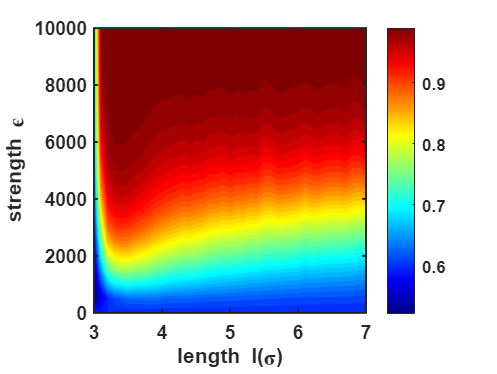

[C,h]=contourf(L,K,Z,50,'--','ShowText','off','LabelSpacing',1000);
h.LevelList=round(h.LevelList,2);  %等高线数值保留小数点后两位
set(h, 'edgecolor','none');
clabel(C,h);

colorbar;
colormap("jet");

set(gca,'linewidth',1,'FontWeight','bold','FontName','arial');
xlabel('length l(\sigma)','FontName','arial','FontWeight','bold'); 
ylabel('strength \epsilon','FontName','arial','FontWeight','bold');

function a= E(r) %定义特定的势能函数E(r)
    e=5000;
    o=1;%计算的其实是o/r
    a=4.*e.*(((r/o).^(-12))-((r/o).^(-6)));
end

function b=P(r) %定义相应的概率分布函数P(r)
    b=exp(-E(r)/(8.31*298));
end

